# Object Detector

Copyright 2018 The MathWorks, Inc.

## Overview

The Object Detector allows you to simulate vision-based object detectors for visualization and algorithm prototyping. It includes a MATLAB and Simulink interface.

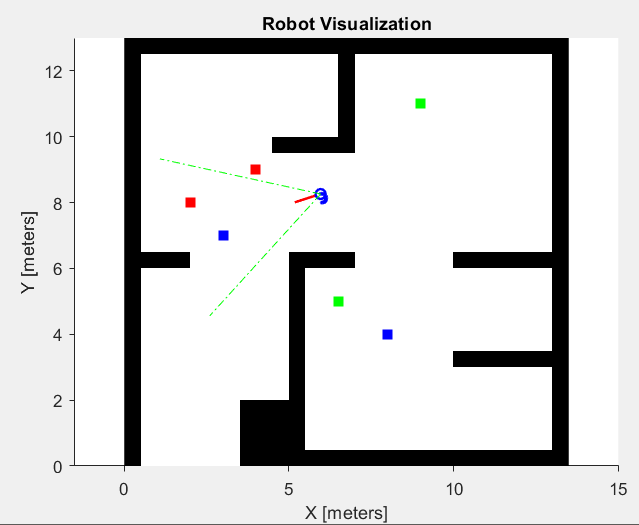

**Properties:**

- **Map: **A [`robotics.OccupancyGrid`](matlab: doc robotics.OccupancyGrid) or [`robotics.BinaryOccupancyGrid`](matlab: doc robotics.BinaryOccupancyGrid)

- **Object detector offset:** A 2-by-1 array of $[x; y]$ offset from the vehicle

- **Object detector angle:** Sensor orientation, in radians, relative to the vehicle $x$-axis 

- **Sensor field of view:** Sensor angular range, in radians, symmetric about the sensor $x$-axis

- **Maximum range:** The sensor maximum range, in meters.

- **Maximum number of detections:** The maximum object detections returned. Detections are sorted from nearest to farthest.

**Inputs:**

- **Pose: **A 3-by-1 array representing the robot pose $[x; y; \theta]$, in meters and radians respectively

- **Objects:** An N-by-3 array whose rows represent the $[x, y, label]$ of objects. The label is an integer value (1, 2, 3, etc.) which is used to simulate object correspondence such as color, markers, etc.

**Outputs:**

- **Detections: **A variable-sized array up to size `maxDetections`-by-3. Each row corresponds to `[range,angle,label]` of an object detection. Range is in meters, and angle is in radians.

## MATLAB Usage

Create an `ObjectDetector` object.

detector = ObjectDetector

detector =   ObjectDetector with properties:

          mapName: ''
     sensorOffset: [0 0]
      sensorAngle: 0
      fieldOfView: 1.0472
         maxRange: 5
    maxDetections: 3

Configure the sensor properties.

load exampleMap
detector.mapName = 'map';
detector.sensorOffset = [0,0];
detector.sensorAngle = 0;
detector.fieldOfView = pi/3;
detector.maxRange = 4;
detector.maxDetections = 3;

Simulate and display the object detections the map and vehicle pose.

objects = [3, 5, 1; 2, 5, 2; 3, 4, 3]; % Each row is [x, y, label]
pose = [2; 4; pi/6];
detections = detector(pose,objects)

detections =     1.0000   -0.5236    1.0000
    1.4142    0.2618    3.0000

Simulate and display the object detections, map, and vehicle pose.

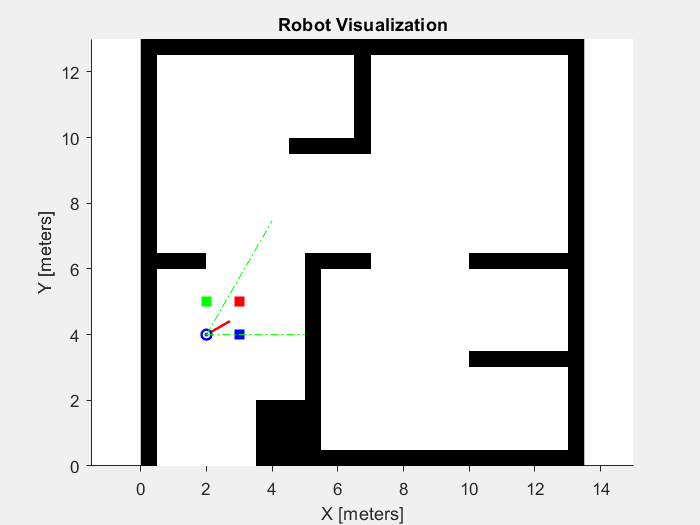

viz = Visualizer2D;
viz.mapName = 'map';
attachObjectDetector(viz,detector);
viz.objectColors = [1, 0, 0; 0, 1, 0; 0, 0, 1]; % Row 1: Red, Row 2: Green, Row 3: Blue
viz(pose,objects)

**Examples**

- [Object detector MATLAB example](matlab: edit mrsExampleObjectDetector)

## Simulink Usage

Use the **Object Detector** block from the **Environments** section of the [block library](matlab: mobileRoboticsLib). 

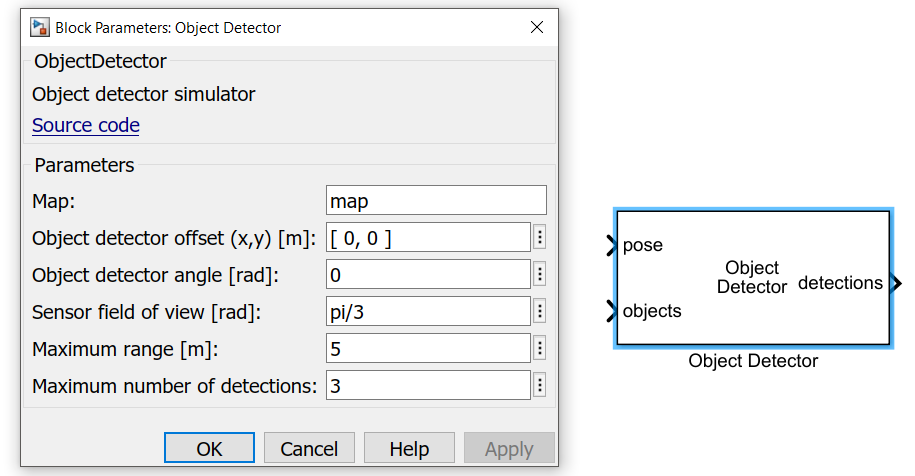

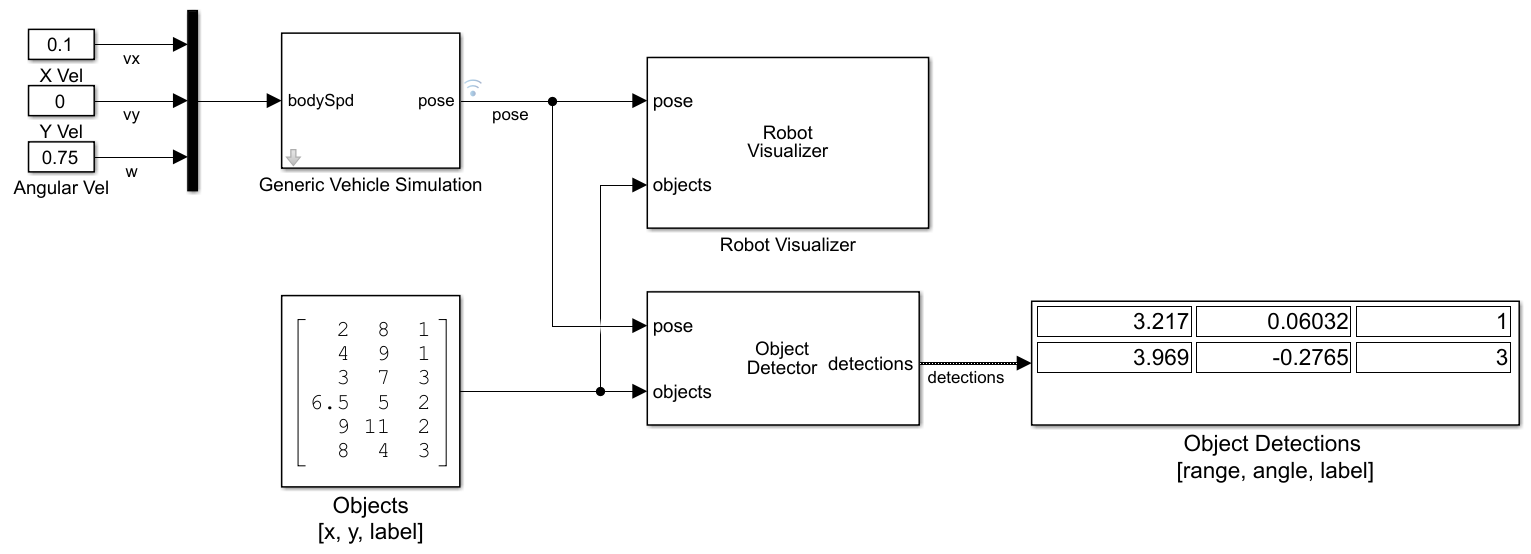

**Examples**

- [Model with Object Detector block](matlab: mrsObjectModel)

- [Model with Lidar Sensor and Object Detector blocks](matlab: mrsLidarAndObjectModel)

- [Object tracking logic example](matlab: mrsObjectTrackingModel)